# **State space transformator**

**Auteurs: Dirk Bouma, Perijn Huijser**

**Project: Tesla coil**

**Vak: Elektro fysica**

**Opdrachtgever: Johannes Bruinsma**

## **Inleiding**

Om de eigenschappen van de tesla coil te bestuderen, gaan wij de transformator modelleren. Dit doen wij door middel van Matlab te gebruiken. Vervolgens kunnen wij onze resultaten van Matlab naar simulink importeren.

Om het beeld van de transformator te verduidelijken hebben wij een schema gemaakt van hoe de transformator circuit eruit komt te zien. Hieraan kunnen wij zien dat wij te maken hebben met twee RLC kringen.

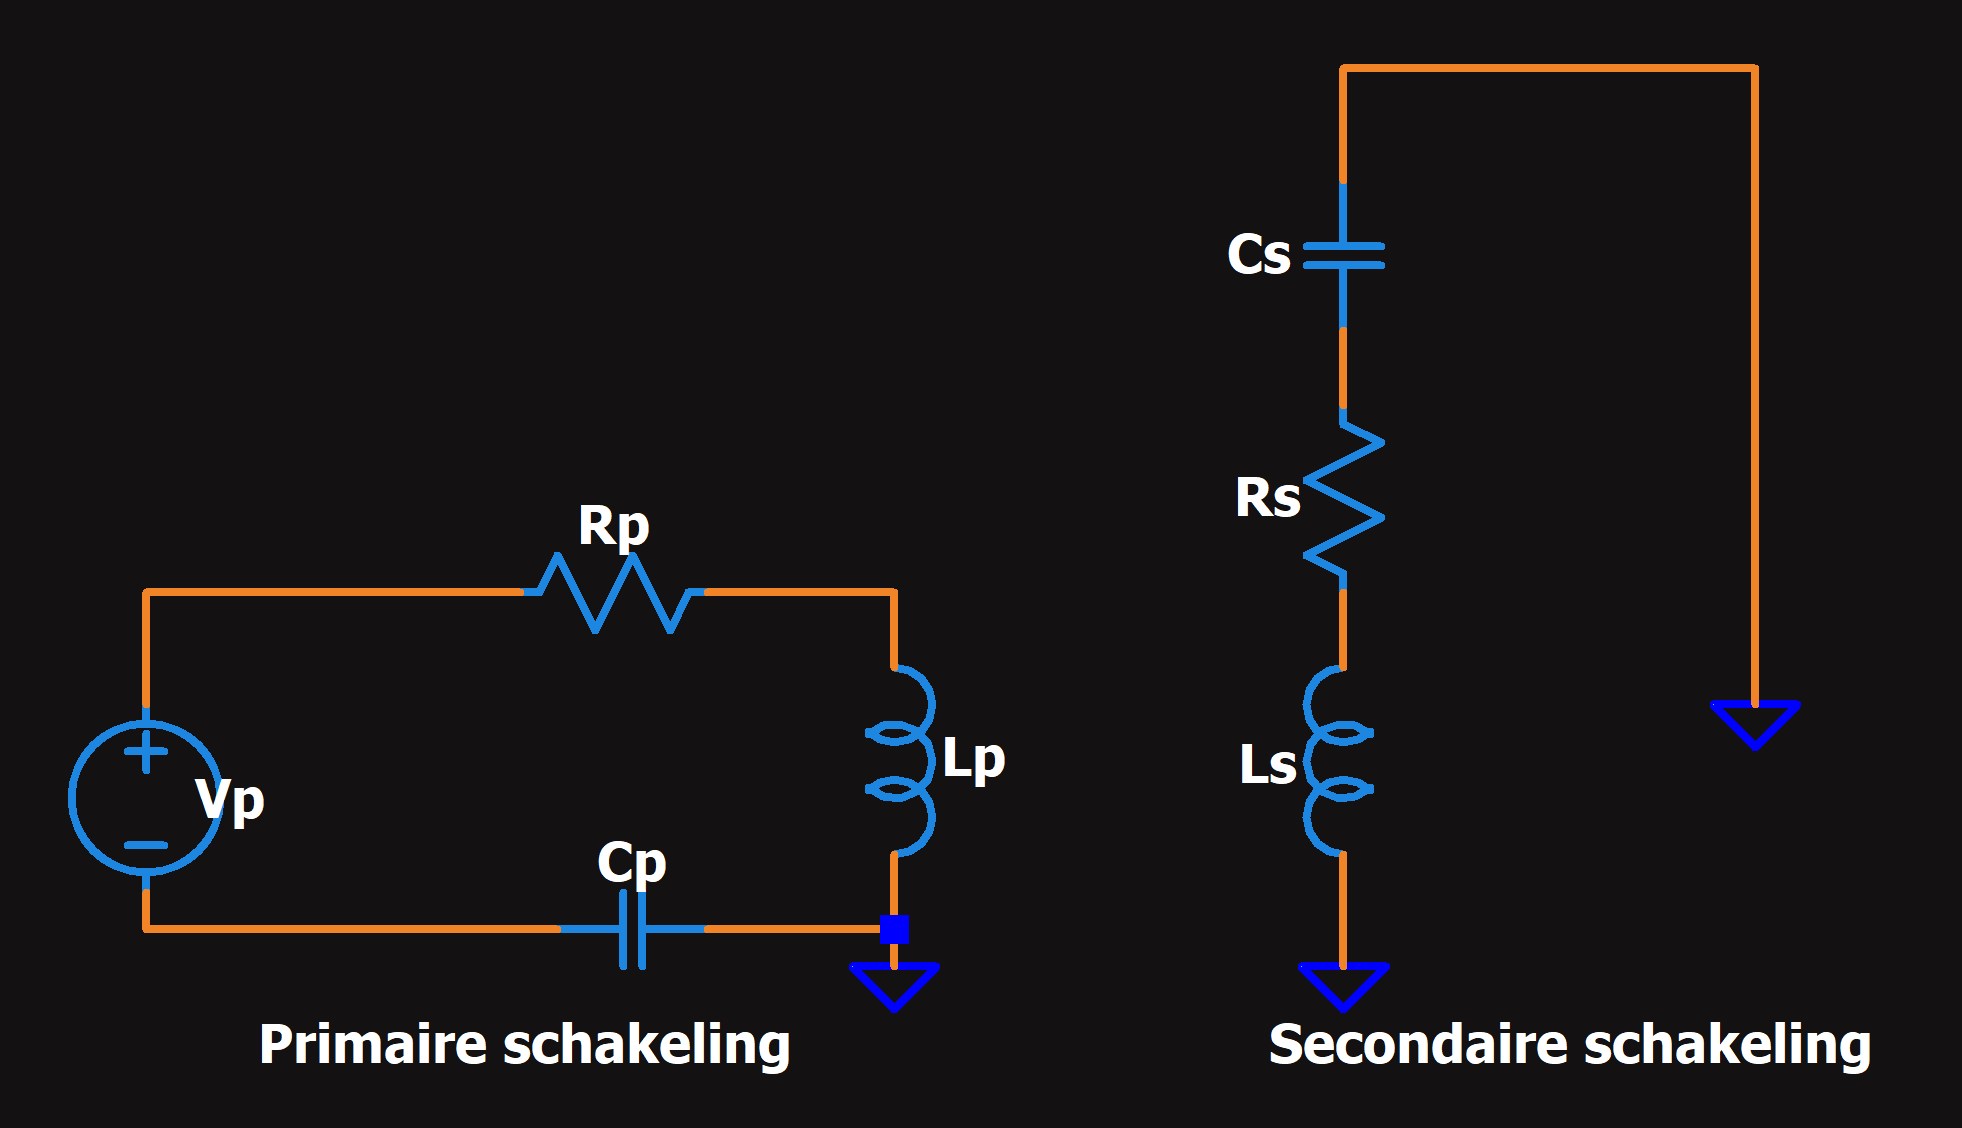

[0.851 0.325 0.098]

ans =     0.8510    0.3250    0.0980


## RLC kringen

Wij hebben met twee RLC kringen te maken. Om de formules te bepalen gaan wij netwerk analyse AC toepassen. De formula voor een serie RLC kring is:


$$V=L\frac{\textrm{dI}}{\textrm{dt}}+\textrm{RI}+\frac{1}{C}\int \textrm{di}\;\textrm{dt}$$


Waarbij:  $V$ - De spanning over de RLC kring

                $\mathrm{I}$ - Stroom door de RLC kring

                $C$ - Capiciteit van de condensator

                $\mathrm{R}$ - Weerstand van de RLC kring

                $L$ - Inductie van de RLC kring

Als wij deze formule gaan invullen voor onze twee RLC kringen, dan krijgen wij:


$$V_p \left(t\right)=L_p \frac{dI_1 }{\textrm{dt}}+R_p I_1 +\frac{1}{C_p }\int di_1 \;\textrm{dt}$$



$$0=L_s \frac{dI_2 }{\textrm{dt}}+R_s I_2 +\frac{1}{C_s }\int di_2 \;\textrm{dt}$$


Dit geeft ons dus twee tweede orde differentiaal vergelijkingen. 

## Wet van Faraday

Volgens de wet van Faraday wordt een spanning geïnduceerd in een elektrische geleider als gevolg van een veranderend magnetisch veld. Door onze primaire RLC-kring met een spanning aan te sturen, varieert de stroom in functie van de tijd. Dit resulteert in een wisselend magnetisch veld opgewekt door de primaire spoel, dat een spanning induceert in de secundaire kring. Er ontstaat dus wederzijdse inductie tussen de spoelen:


$$V_p \left(t\right)=L_p \frac{dI_1 }{\textrm{dt}}+M\;\frac{dI_2 }{\textrm{dt}}+R_p I_1 +\frac{1}{C_p }\int di_1 \;\textrm{dt}$$



$$0=L_s \frac{dI_2 }{\textrm{dt}}+M\;\frac{dI_1 }{\textrm{dt}}+R_s I_2 +\frac{1}{C_s }\int di_2 \;\textrm{dt}$$


Door de wederzijdse inductantie $M$ toe te voegen in onze formules wordt het systeem complexer. Er ontstaat een impedantie 'reflectie', waarbij de primaire en secundaire spoel elkaars impedantie gedeeltelijk ervaren.

Om het effect te analyseren, transformeren we onze vergelijkingen naar het frequentiedomein. Door de secundaire stroom $I_2$ op te lossen en te substitueren in de primaire vergelijking, verkrijgen we een uitdrukking waaruit blijkt dat de primaire impedantie een extra term omvat, genaamd de reflecterende impedantie, veroorzaakt door de koppeling met de secundaire kring.


$$V_p \left(t\right)=j\omega MI_2 +Z_1 I_1$$



$$0=j\omega MI_1 +Z_2 I_2$$


Waarbij $I_2$ gelijk is aan:


$$I_2 \;=-\frac{j\omega M}{Z_2 }I_1$$


Substetueer $I_2$ in de primaire vergelijking.


$$V_p \left(t\right)=Z_1 I_1 +j\omega M\left(-\frac{j\omega M}{Z_2 }I_1 \right)$$


Na versimpelen:

$V_p \left(t\right)=Z_1 I_1 -\frac{{\left(j\omega M\right)}^2 }{Z_2 }I_1$ -> $V_p \left(t\right)=\left(Z_1 +\;\frac{\omega^2 M^2 }{Z_2 }\right)I_1$

Hier kan worden waargenomen dat de impedantie nu uit twee componenten bestaat. Daarnaast kan geconcludeerd worden dat de impedantierreflectie gevoelig is voor zowel de frequentie als de inductieve koppeling, aangezien de wederzijdse inductantie afhangt van de mate van inductieve koppeling. Om het effect van deze impedantierreflectie in het frequentiedomein beter te begrijpen, zullen we dit onderzoeken door middel van een analyse in Matlab.

## State-spaces


$$V_p \left(t\right)=L_p \frac{dI_1 }{\textrm{dt}}+M\;\frac{dI_2 }{\textrm{dt}}+R_p I_1 +\frac{1}{C_p }\int di_1 \;\textrm{dt}$$



$$0=L_s \frac{dI_2 }{\textrm{dt}}+M\;\frac{dI_1 }{\textrm{dt}}+R_s I_2 +\frac{1}{C_s }\int di_2 \;\textrm{dt}$$



$$V_p \left(t\right)=L_p {\ddot{q} }_1 +M{\ddot{q} }_2 +R_p {\dot{q} }_1 +\frac{q_1 }{C_p }$$



$$0=L_s {\ddot{q} }_2 +M{\ddot{q} }_1 +R_s {\dot{q} }_2 +\frac{q_2 }{C_s }$$


clear;

syms V_p(t) L_p R_p C_p L_s R_s C_s q_1 q_2



eqP = V_p == 

$$L\_p = L_{p}$$